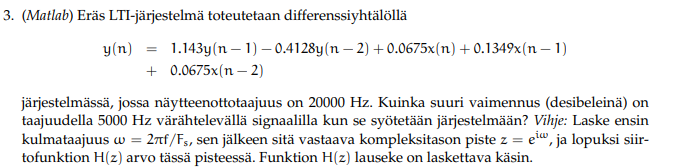

Fs=20000;
f=5000;
w=2*pi*f/Fs;
%y(n) = 1.143y(n − 1) − 0.4128y(n − 2) + 0.0675x(n) + 0.1349x(n − 1) + 0.0675x(n − 2)
%Y(z) = 1.143Y(z)z^-1 − 0.4128Y(z)z^-2 + 0.0675X(z) + 0.1349X(z)z^-1 + 0.0675X(z)z^-2
%Y(z)-1.143Y(z)z^-1 + 0.4128Y(z)z^-2   =  0.0675X(z)+ 0.1349X(z)z^-1 + 0.0675X(z)z^-2
%Y(z)(1-1.143z^-1+0.4128z^-2) = X(z)( 0.0675 + 0.1349 z^-1 + 0.0675 z^-2)
%H(z)=Y(z)/X(z)=( 0.0675 + 0.1349 z^-1 + 0.0675 z^-2)/(1-1.143z^-1+0.4128z^-2)
%sijoitetan z=e^iw
z=exp(1i*w)

z = 0.0000 + 1.0000i

H=( 0.0675 + 0.1349 *z^(-1) + 0.0675*z^(-2))/(1-1.143*z^(-1)+0.4128*z^(-2))

H = -0.0934 - 0.0480i

vaimennus=abs(H)

vaimennus = 0.1050

%db
format short
log10(vaimennus)

ans = -0.9789

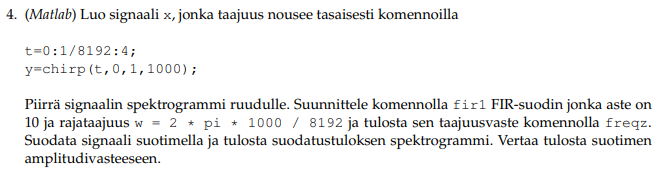

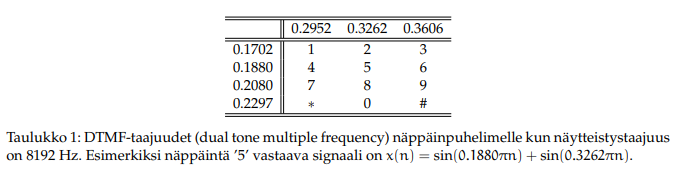

t=0:1/8192:4;
y=chirp(t,0,1,1000);
n=10;
wn=2*pi*1000/8192

wn = 0.7670

b = fir1(n,wn)

b =    -0.0025   -0.0028    0.0343   -0.1083    0.1947    0.7693    0.1947   -0.1083    0.0343   -0.0028   -0.0025


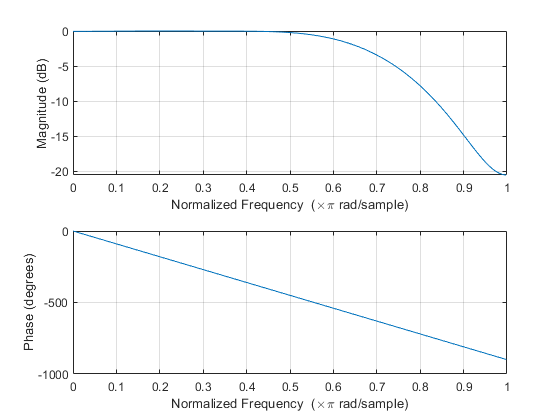

freqz(b)

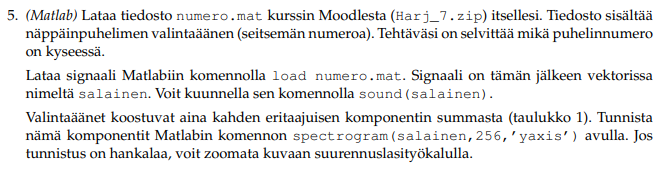

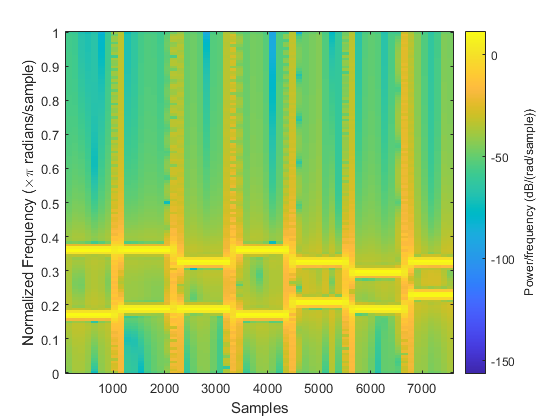

% 3653840
load numero.mat
sound(salainen)
spectrogram(salainen, 256,'yaxis')